# Ignition Time Detection

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
% format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

## Import Signal Data

## Load "Raw" Signal

**Note: **Details on DAQ system setting are required, to check if any hardware filters has been used.

% Load data
load('E2038.mat');  

% Offset correction
% Offset_correction_mean = mean(p(1:100,1:12),1);
% Offset_correction_std = std(p(1:100,1:12),1);
Offset_correction_mean = mean(p(1:100,:),1);
Offset_correction_std = std(p(1:100,:),1);

% dataPoffsetCorrected = p(:,1:12) - Offset_correction_mean;
dataPoffsetCorrected = p(:,:) - Offset_correction_mean;
Fs = fs;  % Sampling frequency in Hz
t = (0:length(dataPoffsetCorrected)-1)'/Fs;

## Option 1: Adjust the `dpdt_threshold`

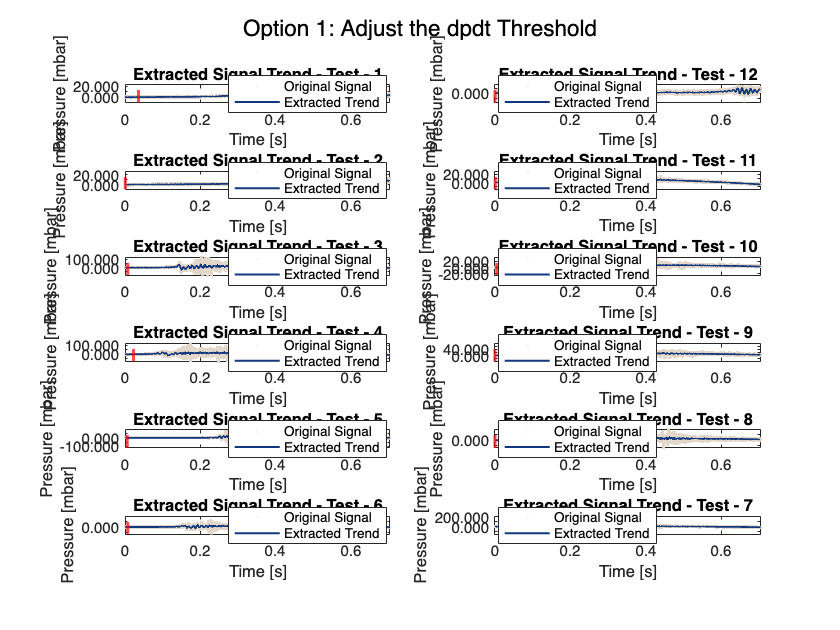

% Define number of tests based on available columns
test_numbers = 1:size(dataPoffsetCorrected, 2);

% Define test pairs for subplot arrangement
test_pairs = [1, 12; 2, 11; 3, 10; 4, 9; 5, 8; 6, 7];  
rows = 6;
cols = 2;

% Preallocate arrays
ignition_times = NaN(length(test_numbers), 1); % Use NaN for missing values
smoothed_pressure = zeros(size(dataPoffsetCorrected)); % Preallocate for efficiency

% Define detection thresholds
% dpdt_threshold = 0.005; % Change in pressure per second
% pressure_threshold = 0.01; % Minimum pressure level above baseline
% Define detection thresholds (adjusting dpdt_threshold)
dpdt_threshold = 0.005; % Reduced threshold for earlier detection
pressure_threshold = 0.05; % Keep initial value for now

figure;
for i = 1:size(test_pairs,1) % Loop over row pairs
    for j = 1:cols % Loop over columns
        test_index = test_pairs(i, j); % Get test number for subplot
        subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
        span = 9999;
        polyOrder = 2;
        % Smooth the pressure signal
        smoothed_pressure(:,test_index) = smooth(dataPoffsetCorrected(:,test_index), span, 'sgolay', polyOrder);
        
        % Compute first derivative (dP/dt)
        dp_dt = diff(smoothed_pressure(:,test_index)) ./ diff(t);

        % Adjust time vector for derivative length
        time_dpdt = t(1:end-1);

        % Find the first moment where dP/dt exceeds threshold and pressure is above baseline
        ignition_idx = find(dp_dt > dpdt_threshold & smoothed_pressure(1:end-1, test_index) > pressure_threshold * abs(mean(smoothed_pressure(1:100, test_index))), 1);

        % Store ignition time if detected
        if ~isempty(ignition_idx)
            ignition_times(test_index) = time_dpdt(ignition_idx);
        end
        
        % Scatter plot of original signal (using your copper color, semi-transparent)
        scatter(t, dataPoffsetCorrected(:, test_index)*1000, '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index)*1000, 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        ytickformat('%.3f')  % Uses compact engineering notation
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation
        % Mark detected ignition time with a red dashed line
        if ~isnan(ignition_times(test_index))
            xline(ignition_times(test_index), 'r--', 'LineWidth', 2);
        end

        % Title and labels
        title(['Ignition Time Detection - Test - ' num2str(test_index)]);
        title(['Extracted Signal Trend - Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [mbar]');
        box on;
        legend('Original Signal', 'Extracted Trend', 'Location', 'best');
        axis tight;
        sgtitle('Option 1: Adjust the dpdt Threshold')
        % sgtitle({'Repeated Test Overview (Smoothed by Savitzky-Golay Filter)',sprintf('\\fontsize{10}(Span: %d | Polynomial Degree: %d)', span, polyOrder)})
    end
end
 hold off

## Option 2: Use a More Adaptive Pressure Threshold

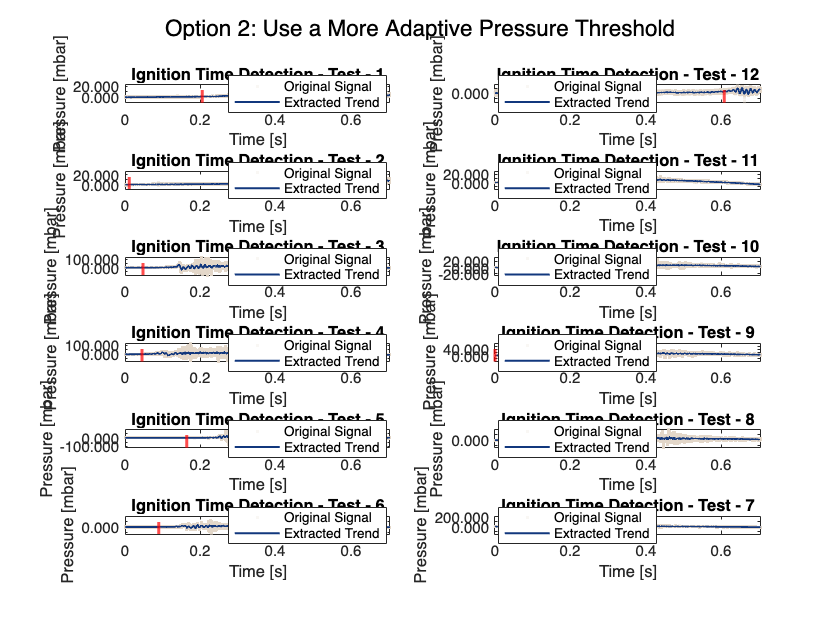

% Define number of tests based on available columns
test_numbers = 1:size(dataPoffsetCorrected, 2);

% Define test pairs for subplot arrangement
test_pairs = [1, 12; 2, 11; 3, 10; 4, 9; 5, 8; 6, 7];  
rows = 6;
cols = 2;

% Preallocate arrays
ignition_times = NaN(length(test_numbers), 1); % Use NaN for missing values
smoothed_pressure = zeros(size(dataPoffsetCorrected)); % Preallocate for efficiency

% Define detection thresholds
dpdt_threshold = 0.00125; % Reduced threshold for earlier detection
% pressure_threshold = 0.01; % Keep initial value for now

figure;
for i = 1:size(test_pairs,1) % Loop over row pairs
    for j = 1:cols % Loop over columns
        test_index = test_pairs(i, j); % Get test number for subplot
        subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
        
        % Smooth the pressure signal
        smoothed_pressure(:,test_index) = smooth(dataPoffsetCorrected(:,test_index), 9999, 'sgolay', 2);
        
        % Compute first derivative (dP/dt)
        dp_dt = diff(smoothed_pressure(:,test_index)) ./ diff(t);
        
        % Adjust time vector for derivative length
        time_dpdt = t(1:end-1);
        
        % Adaptive pressure threshold based on noise level
        baseline_std = std(smoothed_pressure(1:10000, i)); % Estimate noise from first 100 samples
        % baseline_std = max(abs(dataPoffsetCorrected(1:100, i))); % Estimate noise from first 100 samples
        pressure_threshold = 5 * baseline_std; % Set threshold at 3x noise level
        
        % Find the first moment where dP/dt exceeds threshold and pressure is above baseline
        ignition_idx = find(dp_dt > dpdt_threshold & smoothed_pressure(1:end-1, test_index) > pressure_threshold, 1);
        
        % Store ignition time if detected
        if ~isempty(ignition_idx)
            ignition_times(test_index) = time_dpdt(ignition_idx);
        end
        
        % Scatter plot of original signal (using your copper color, semi-transparent)
        scatter(t, dataPoffsetCorrected(:, test_index)*1000, '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index)*1000, 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        ytickformat('%.3f')  % Uses compact engineering notation
        ax = gca;
        ax.YAxis.Exponent = 0;  % Disables scientific notation
        % Mark detected ignition time with a red dashed line
        if ~isnan(ignition_times(test_index))
            xline(ignition_times(test_index), 'r--', 'LineWidth', 2);
        end
        
        % Title and labels
        title(['Ignition Time Detection - Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [mbar]');
        box on;
        legend('Original Signal', 'Extracted Trend', 'Location', 'best');
        axis tight;
        sgtitle('Option 2: Use a More Adaptive Pressure Threshold')
       
    end

end
 hold off

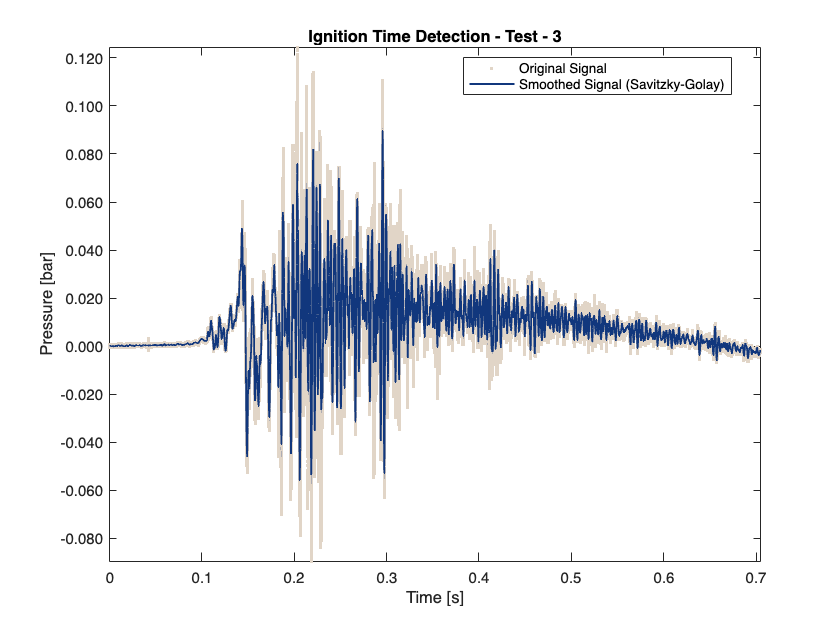

% Smooth the pressure signal
testNum = 3;
pData = dataPoffsetCorrected(:,testNum);
smoothed_pressure = smooth(pData, 2499, 'sgolay', 2); 
% yy = smooth(y,span,'sgolay',degree) uses the number of data points specified by 
% span in the Savitzky-Golay calculation. span must be odd and degree must be less than span.

% Scatter plot of original signal
figure
scatter(t, pData, '.', 'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, 'MarkerEdgeAlpha', 1);
hold on;
% Plot smoothed signal
plot(t, smoothed_pressure, 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
% Title and labels
title(['Ignition Time Detection - Test - ' num2str(testNum)]);
        xlabel('Time [s]');
        ylabel('Pressure [bar]');
        ytickformat('%.3f')  % Uses compact engineering notation
        box on;
        legend('Original Signal', 'Smoothed Signal (Savitzky-Golay)', 'Location', 'best');
        axis tight;
hold off

**Data Sampling on Region of Interest (RoI - Ignition)**

sampledTimeIncrement = 200e-3; % [s]
sampledTime_inital = 0e-3; % [s]
sampledTime_final = sampledTime_inital + sampledTimeIncrement; % [s]
sampledPoints_inital = Fs * sampledTime_inital + 1;
sampledPoints_final = Fs * sampledTime_final;

Find the "MaxNumChanges" points where the mean of the signal changes most significantly.

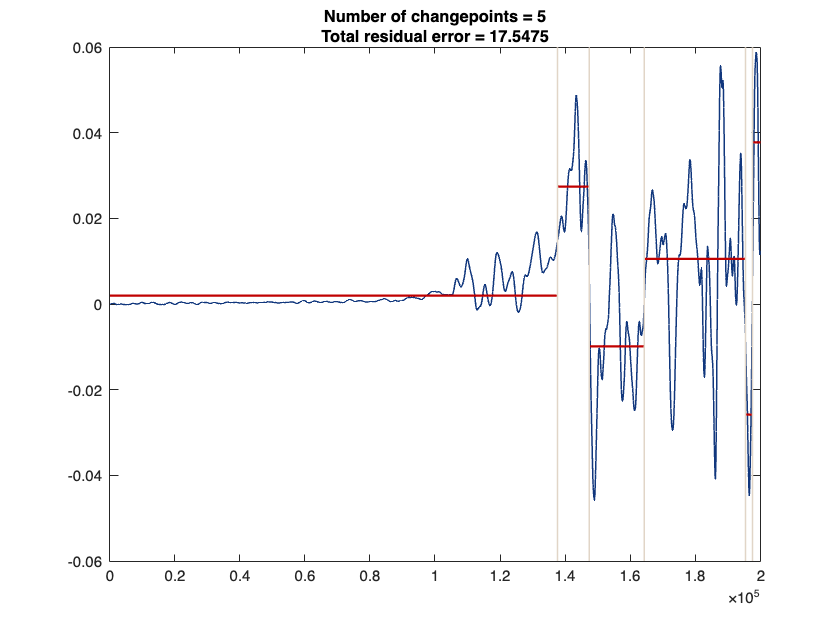

figure
% subplot(3,1,1)
findchangepts(smoothed_pressure(sampledPoints_inital:sampledPoints_final),MaxNumChanges=5)
ax = gca;

% Lines showing the breaks in regions
ax.Children(1).LineWidth = 1;
ax.Children(1).LineStyle = '-';
ax.Children(1).Color = AuxFcn_GS.LUCopper_Light;

% Lines showing the breaks in regions
ax.Children(2).LineWidth = 1.5;
ax.Children(2).LineStyle = '-';
ax.Children(2).Color = AuxFcn_GS.Red_Dark;

% Original data
ax.Children(3).LineWidth = 1;
ax.Children(3).LineStyle = '-';
ax.Children(3).Color = AuxFcn_GS.LUBlue;

Find the "MaxNumChanges" points where the root-mean-square level of the signal changes most significantly.

% subplot(3,1,2)
% figure
% findchangepts(smoothed_pressure(sampledPoints_inital:sampledPoints_final),MaxNumChanges=10,Statistic="rms")

Find the "MaxNumChanges" points where the mean and standard deviation of the signal change the most.

% subplot(3,1,3)
% findchangepts(smoothed_pressure(sampledPoints_inital:sampledPoints_final),MaxNumChanges=10,Statistic="std")

Find the points where the mean and the slope of the signal change most abruptly. Specify a minimum residual error improvement of 0.6.

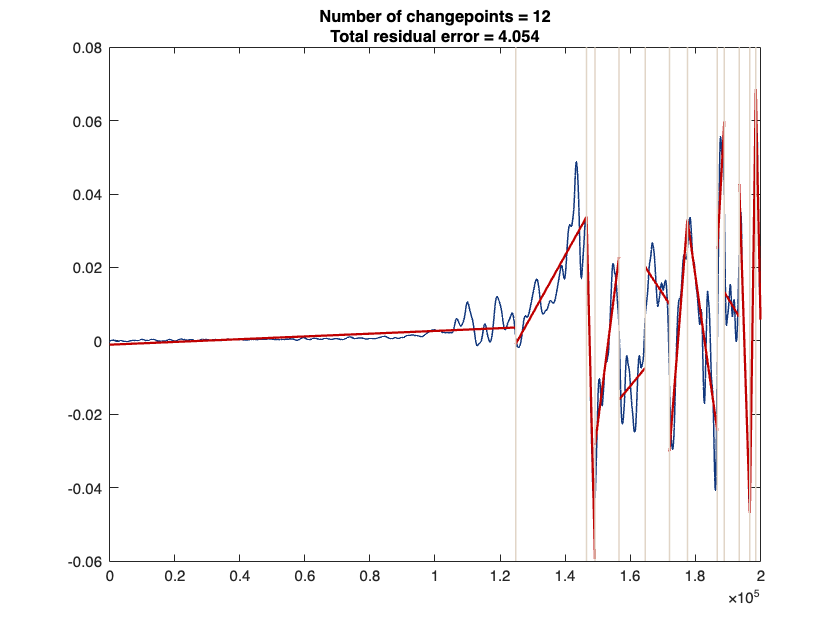

findchangepts(smoothed_pressure(sampledPoints_inital:sampledPoints_final),'Statistic','linear','MinThreshold',0.6)
ax = gca;

% Lines showing the breaks in regions
ax.Children(1).LineWidth = 1;
ax.Children(1).LineStyle = '-';
ax.Children(1).Color = AuxFcn_GS.LUCopper_Light;

% Lines showing the breaks in regions
ax.Children(2).LineWidth = 1.5;
ax.Children(2).LineStyle = '-';
ax.Children(2).Color = AuxFcn_GS.Red_Dark;
% Original data
ax.Children(3).LineWidth = 1;
ax.Children(3).LineStyle = '-';
ax.Children(3).Color = AuxFcn_GS.LUBlue;

Compute the mean and standard deviation of the first 25 samples. 

Apply cusum using these numbers as the target mean and the target standard deviation. 

Highlight the point where the cumulative sum drifts more than five standard deviations beyond the target mean. Set the minimum detectable mean shift to one standard deviation.

**Data Sampling on Region of Interest (RoI - Ignition)**

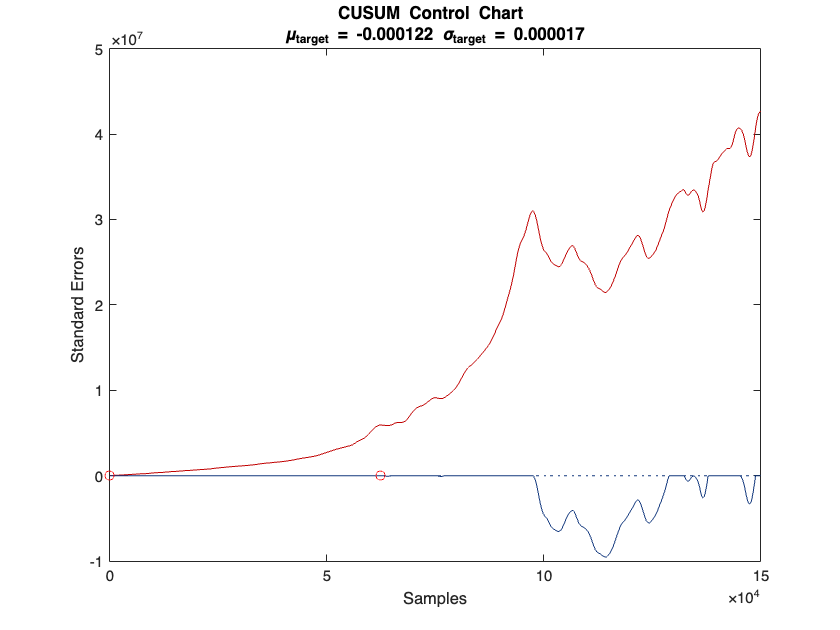

sampledTimeIncrement = 150e-3; % [s]
sampledTime_inital = 50e-3; % [s]
sampledTime_final = sampledTime_inital + sampledTimeIncrement; % [s]
sampledPoints_inital = Fs * sampledTime_inital + 1;
sampledPoints_final = Fs * sampledTime_final;


mfnc = mean(smoothed_pressure(1:100));
sfnc = std(smoothed_pressure(1:100));
% [iupper,ilower,uppersum,lowersum] = cusum(smoothed_pressure(sampledPoints_inital:sampledPoints_final),5,0.5,mfnc,sfnc)
% cusum(smoothed_pressure(sampledPoints_inital:sampledPoints_final),10,1,mfnc,sfnc)

cusum(smoothed_pressure(sampledPoints_inital:sampledPoints_final),5,1,mfnc,sfnc)
ax = gca;
% get (ax)
% ax.YLabel.String = 'test'
% ax.Children(1).Color = AuxFcn_GS.Red_Dark;
% ax.Children(2).Color = AuxFcn_GS.Red_Dark;
ax.Children(3).Color = AuxFcn_GS.LUBlue;
ax.Children(4).Color = AuxFcn_GS.Red_Dark;
ax.Children(5).Color = AuxFcn_GS.LUBlue;
ax.Children(6).Color = AuxFcn_GS.Red_Dark;

[iupper,ilower] = cusum(smoothed_pressure(sampledPoints_inital:sampledPoints_final),5,1,mfnc,sfnc)

iupper = 2

ilower = 62525

% climit = 5;
% mshift = 1;
% tmean = mean(smoothed_pressure(1:100));
% tdev = std(smoothed_pressure(1:100));
% cusum(smoothed_pressure(sampledPoints_inital:sampledPoints_final),climit,mshift,tmean,tdev)

## Selected Data for Analysis

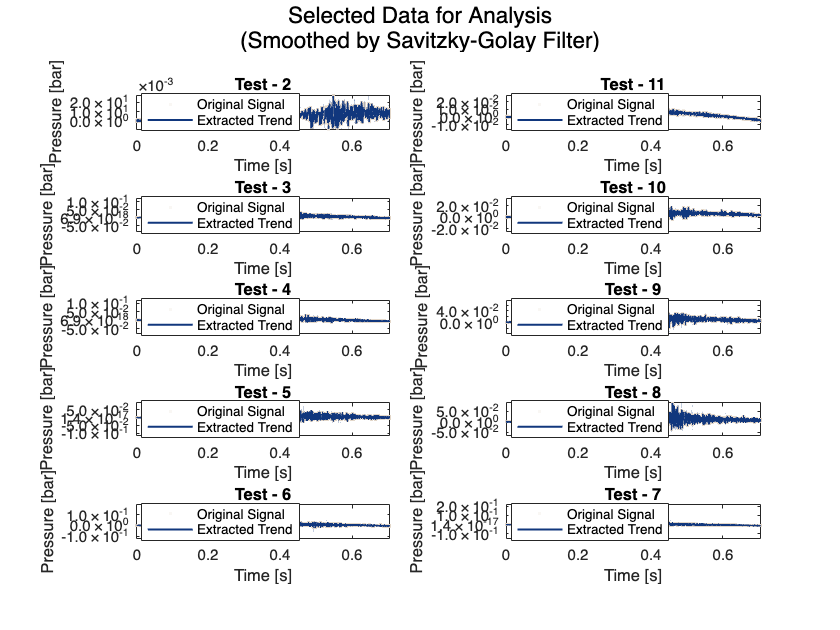

% Define number of tests based on available columns
test_numbers = [2,3,4,5,6,7,8,9,10,11];

% Define test pairs for subplot arrangement
test_pairs = [2, 11; 3, 10; 4, 9; 5, 8; 6, 7];  
rows = 5;
cols = 2;

% Preallocate arrays
ignition_times = NaN(length(test_numbers), 1); % Use NaN for missing values
smoothed_pressure = zeros(size(dataPoffsetCorrected)); % Preallocate for efficiency

% Define detection thresholds
dpdt_threshold = 0.00125; % Reduced threshold for earlier detection
% pressure_threshold = 0.01; % Keep initial value for now

figure;
for i = 1:size(test_pairs,1) % Loop over row pairs
    for j = 1:cols % Loop over columns
        test_index = test_pairs(i, j); % Get test number for subplot
        subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
        
        % Smooth the pressure signal
        smoothed_pressure(:,test_index) = smooth(dataPoffsetCorrected(:,test_index), 100, 'sgolay', 2);      
        
        % Scatter plot of original signal
        scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index), 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        ytickformat('%.1e')  % Uses compact engineering notation

        % Title and labels
        % title(['Ignition Time Detection - Test - ' num2str(test_index)]);
        title(['Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [bar]');
        box on;
        legend('Original Signal', 'Extracted Trend', 'Location', 'best');
        axis tight;
        sgtitle({'Selected Data for Analysis','(Smoothed by Savitzky-Golay Filter)'})
       
    end

end
 hold off

## `ischange` 

 % Smooth the pressure signal
smoothed_pressure = smooth(dataPoffsetCorrected(:,3), 2499, 'sgolay', 2); 
ignitionRegion =smoothed_pressure(sampledPoints_inital:sampledPoints_final);
[TF,S1,S2] = ischange(ignitionRegion,'linear','Threshold',1000);
figure
plot(t(sampledPoints_inital:sampledPoints_final),ignitionRegion,'.','Color',AuxFcn_GS.LUBlue)
hold on
segline = S1.*(t(sampledPoints_inital:sampledPoints_final)) + S2;
plot(t(sampledPoints_inital:sampledPoints_final),segline);              
legend('Data','Linear Regime')

figure
A = smoothed_pressure(sampledPoints_inital:sampledPoints_final);
x = t(sampledPoints_inital:sampledPoints_final);
TF = islocalmax(A);
plot(x,A,x(TF),A(TF),'r*')

% figure
% rows = 6;
% cols = 2;
% test_pairs = [1, 12; 2, 11; 3, 10; 4, 9; 5, 8; 6, 7]; % Define pair arrangement
% 
% for i = 1:size(test_pairs,1) % Loop over rows
%     for j = 1:cols % Loop over columns
%         test_index = test_pairs(i, j); % Get test number for subplot
%         subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
% 
%         scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
%             'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
%             'MarkerEdgeAlpha', 0.2);  % 20% opacity
%         hold on
%         plot(t, results(test_index).SignalRecon, 'Color', AuxFcn_GS.LUBlue);
%         title(['Extracted Trend at (' num2str(results(test_index).Passbands(MaxNumPeaks,1), '%.0f') ...
%                ' - ' num2str(results(test_index).Passbands(MaxNumPeaks,2), '%.0f') ') [Hz]' ...
%                ' - Test - ' num2str(test_index)]);
%         xlabel('Time [s]');
%         ylabel('Pressure [bar]');
%         box on
%         legend('Original Signal', 'Extracted Trend','Location','best');
%         axis tight
%     end
% end